# ELEX7620 Lab 8

Name:  Ryan Wong, A00958475, and set:T

Objective:  To implement an LPF IIR filter on the FM4‐176L‐S6E2CC‐ETH platform. 

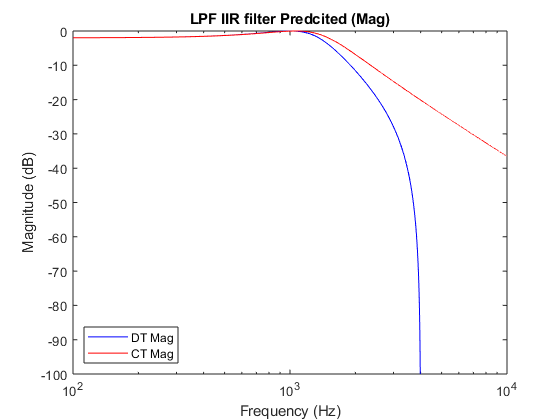

fs = 8000;
Y = [0.1289577395 0.257915479 0.1289577395];
X = [1 -0.812258964 0.4616516598];
[h, f] = freqz(Y, X,512, fs);

a = [58072962];
b = [1 7576 73109527];
H = tf(a,b);

freq = 1:1:10^4;
Dmag = 20*log10(abs(h(:,:)));
Dphase = unwrap(angle(h(:,:))) * 57.2958; 

[mag, phase] = bode(H,2*pi*freq);
mag_dB = 20*log10(abs(mag(:,:)));

figure(1)
clf
semilogx(f,Dmag, "b-")
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('LPF IIR filter Predcited (Mag)')
hold on
semilogx(freq,mag_dB,'r-')
legend('DT Mag','CT Mag', 'location','southwest')
xlim([100 10^4])
ylim([-100 0])
hold off

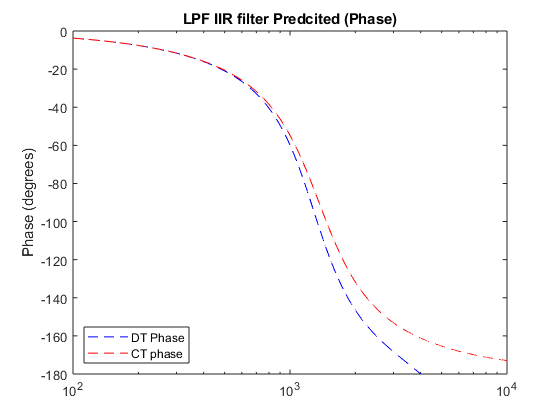


figure(2)
clf
xlabel('Frequency (Hz)')
semilogx(f,Dphase(:,:),'b--')
ylabel('Phase (degrees)')
hold on
semilogx(freq,phase(:,:),'r--')
legend('DT Phase','CT phase', 'location','southwest')
xlim([100 10^4])
title('LPF IIR filter Predcited (Phase)')
hold off

Gain at 1500Hz = -3.889dB

## IIR LPF Filter Calculations

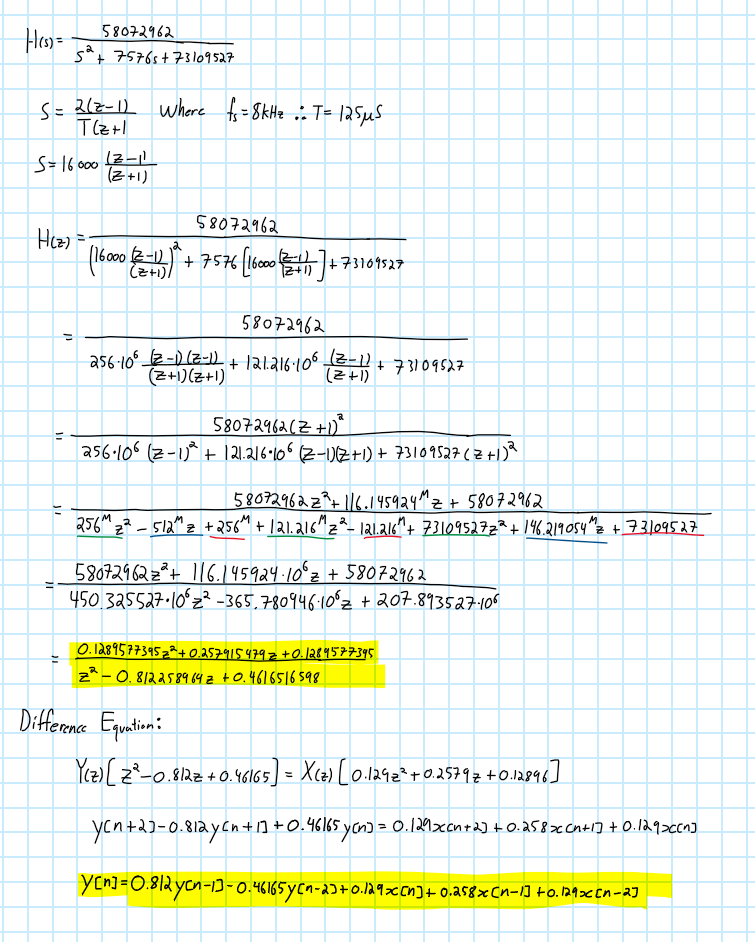

M = idpoly(X, Y, 'NoiseVariance', 0) %determine the difference equation


M =
Discrete-time ARX model:  A(z)y(t) = B(z)u(t)
  A(z) = 1 - 0.8123 z^-1 + 0.4617 z^-2       
                                             
  B(z) = 0.129 + 0.2579 z^-1 + 0.129 z^-2    
                                             
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=2   nb=3   nk=0
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.


## Measurements

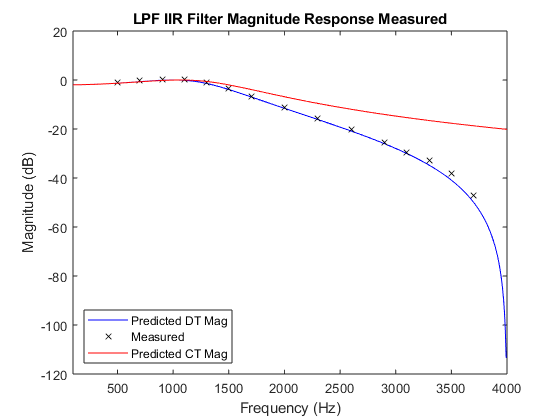

%Measured data; each triplet [f,vout,delay] is 
% f = frequency in Hz
% vout = output voltage, peak to peak
% delay = time delay between input to output, in seconds
measured = [[500,0.97 ]
            [700, 1.03]
            [900, 1.09]
            [1100, 1.11]
            [1300, 0.95]
            [1500, 0.730]
            [1700, 0.49]
            [2000, 0.30]
            [2300, 0.172]
            [2600, 00.106]
            [2900, 0.058]
            [3100, 0.0356]
            [3300, 0.024]
            [3500, 0.013]
            [3700, 0.0048]
           ];

       
           
%Amplitude of input sine wave, peak to peak
%YOU MAY NEED TO ADJUST THIS BASED ON YOUR SETUP
vin = 1.07;


meas_freq = measured(:,1);
meas_mag_dB = 20*log10(measured(:,2)/vin);


figure(3)
clf
plot(f,Dmag,'b-',meas_freq,meas_mag_dB,'kx')
hold on
plot(freq,mag_dB,'r-')
xlim([100 4000])
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('LPF IIR Filter Magnitude Response Measured')
legend('Predicted DT Mag', 'Measured', 'Predicted CT Mag', 'location','southwest')

## C code for FM4-176L-S6E2CC-ETH